# 6.2 设计Butterworth低通数字滤波器

## 6.2（1）利用冲激响应不变法设计Butterworth滤波器：

clear all;
close all;
% 数字滤波器指标:
wp = 0.2*pi; % 数字通带频率(Hz)
ws = 0.5*pi; % 数字阻带频率(Hz)
Rp = 3; % 通带波动(dB)
Rs = 30; % 阻带波动(dB)
% 模拟原型指标对频率的逆映射
T = 0.00001; Fs=1/T; % 置 Fs=100000
OmegaP = wp*Fs; % 原型通带频率
OmegaS = ws*Fs; % 原型阻带频率
% 模拟巴特沃思原型滤波器计算:
[N,OmegaC] =buttord(OmegaP,OmegaS,Rp,Rs,'s') % 原型的阶数和截止频率计算

N = 4

OmegaC = 6.6248e+04

%%***巴特沃思滤波器阶次 = 4
[z0,p0,k0] = buttap(N); % 归一化巴特沃思原型设计函数
p = p0*OmegaC; z = z0*OmegaC; % 将零极点乘以 Omegac，得到非归一化零极点
k = k0*OmegaC^N; % 将 k0 乘以 Omegac^N,得到非归一化 k
num = k*real(poly(z)); % 由零点计算分子系数向量
den = real(poly(p)) % 由极点计算分母系数向量

den = 	1.0e+19 *

    0.0000    0.0000    0.0000    0.0001    1.9262


% 脉冲响应不变法变换:
[bd,ad] = impinvar(num,den,1/T) % 调用脉冲响应不变法函数

bd =    -0.0000    0.0204    0.0520    0.0086


ad =     1.0000   -2.3202    2.2299   -1.0058    0.1771


wx = [OmegaP,OmegaS];
Hx = freqs(num,den,wx)% 计算该两点上的幅特性

Hx =   -0.7627 - 0.1505i   0.0134 + 0.0286i


dbHx=20*log10(abs(Hx)) % 化为分贝值，检验是否达到要求

dbHx =    -2.1872  -30.0000


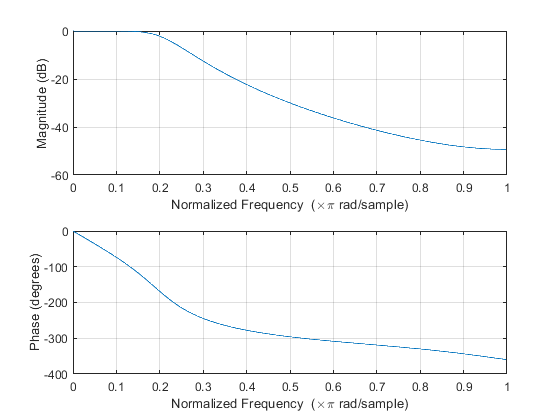

freqz(bd,ad);

## 6.2（2）利用双线性Z变换法设计Butterworth滤波器：

clear all;
close all;
% 数字滤波器指标:
wp = 0.2*pi; % 数字通带频率(Hz)
ws = 0.5*pi; % 数字阻带频率(Hz)
Rp = 3; % 通带波动(dB)
Rs = 30; % 阻带波动(dB)
% 模拟原型指标对频率的逆映射
T = 0.00001; Fs=1/T; % 置 Fs=100000
OmegaP=2*Fs*tan(wp/2); % 给出原始要求
OmegaS=2*Fs*tan(ws/2); % 给出原始要求

[N,Wn]=buttord(OmegaP,OmegaS,Rp,Rs,'s');  %选择模拟巴特沃斯低通滤波器的最小阶数 
[z,p,k]=buttap(N);          %创建巴特沃斯模拟低通滤波器 
[Bp,Ap]=zp2tf(z,p,k)        %由零点、极点、增益确定传输函数的分子与分母的系数 

Bp =      0     0     0     0     1


Ap =     1.0000    2.6131    3.4142    2.6131    1.0000


[b,a]=lp2lp(Bp,Ap,Wn);      %模拟低通滤波器到模拟低通滤波器的转换 

[bz,az]=bilinear(b,a,Fs)

bz =     0.0108    0.0431    0.0646    0.0431    0.0108


az =     1.0000   -1.9358    1.6940   -0.7018    0.1160


figure(1); 
wx = [OmegaP,OmegaS];
Hx = freqs(b,a,wx)% 计算该两点上的幅特性

Hx =   -0.5997 - 0.7280i   0.0134 + 0.0286i


dbHx=20*log10(abs(Hx)) % 化为分贝值，检验是否达到要求

dbHx =    -0.5081  -30.0000


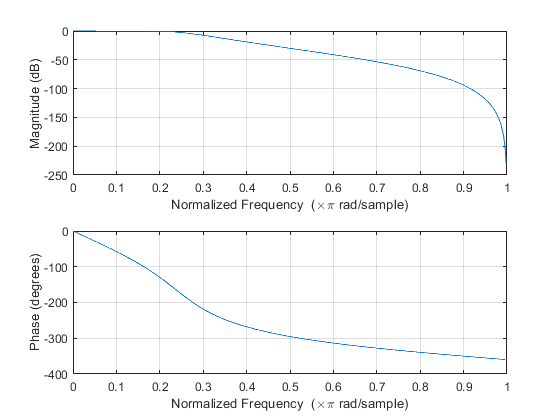

freqz(bz,az);